In this first example I have set the averaging type to arithmetic. The 'type' variable can be chaged to geometric if that type of Asian option is desirable for the simulation. Each one of the following variables of function 'AsianOptionPricing' can be adjusted to the users requirments. The type of Asian option being priced is a discrete Asian option. The following example is without any control variates.

rng;% reset the random number generator
S0 = 100; % Initial stock price
K = 130; % Strike price
r = 0.2; % Risk-free interest rate
T = 1; % Time to maturity
sigma = 0.2; % Volatility
N = 100; % Number of time steps
M = 100000; % Number of simulated paths
type = 'arithmetic'; % Type of Asian option ('arithmetic' or 'geometric')
useControlVariate = false;

[callPrice, putPrice, callPayoff, putPayoff, S] = AsianOptionPricing(S0, K, r, T, sigma, N, M, type,useControlVariate);
fprintf('Asian put option price: %f\n', putPrice);

Asian put option price: 16.210993


fprintf('Asian call option price: %f\n',callPrice);

Asian call option price: 0.523240


The following figure shows the distribution of the payoff for both the call and put Asian option priced above in the form of histograms. It represents the frequency of determined payoffs by the Monte Carlo simulation I ran.

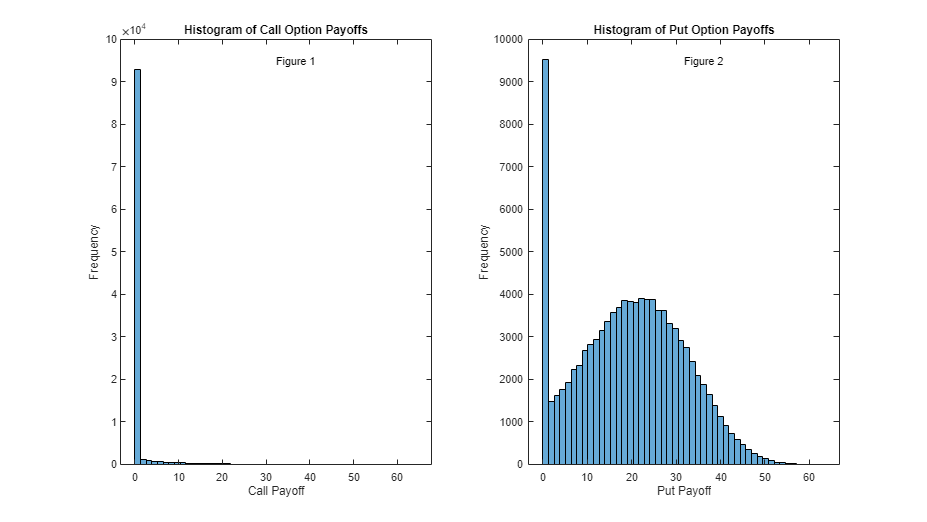

figure('Name','figure 1', 'units','normalized','outerposition',[0 0 1 1]); 

subplot(1, 2, 1);
histogram(callPayoff, 50);
title('Histogram of Call Option Payoffs');
xlabel('Call Payoff');
ylabel('Frequency');
text(0.5,0.95,'Figure 1','Units','normalized');

subplot(1, 2, 2);
histogram(putPayoff, 50);
title('Histogram of Put Option Payoffs');
xlabel('Put Payoff');
ylabel('Frequency');
text(0.5,0.95,'Figure 2','Units','normalized');

In order to improve performance I added a variance reduction technique known as a control variate. Here I used a European option priced on the same variables. To price the European option I used the Black-Scholes-Merton model and created a function to do so.

rng;% reset the random number generator
S0 = 100; % Initial stock price
K = 76; % Strike price
r = 0.02; % Risk-free interest rate
T = 1; % Time to maturity
sigma = 0.2; % Volatility
N = 100; % Number of time steps
M = 100000                                                                                                                                                     ; % Number of simulated paths
type = 'arithmetic'; % Type of Asian option ('arithmetic' or 'geometric')
useControlVariate = false;

%Initializing the Asian Option pricing without Control Variate
[callPrice, putPrice, callPayoff, putPayoff, S,discountFactor] = AsianOptionPricing(S0, K, r, T, sigma, N, M, type, useControlVariate);
fprintf('Asian put option price (no control variate): %f\n', putPrice);

Asian put option price (no control variate): 0.018988


fprintf('Asian call option price (no control variate): %f\n', callPrice);

Asian call option price (no control variate): 24.469040


% Initializing the Asian Option pricing with Control Variate
useControlVariate = true;
[callPriceCV, putPriceCV, callPayoffCV, putPayoffCV, SCV,discountFactorCV] = AsianOptionPricing(S0, K, r, T, sigma, N, M, type, useControlVariate);
fprintf('Asian put option price (control variate): %f\n', putPriceCV);

Asian put option price (control variate): 0.018957


fprintf('Asian call option price (control variate): %f\n', callPriceCV);

Asian call option price (control variate): 24.272396


The following figure is the same type of histogram as before but this time adding graphs for the asian put and call options with control variates for comparison.

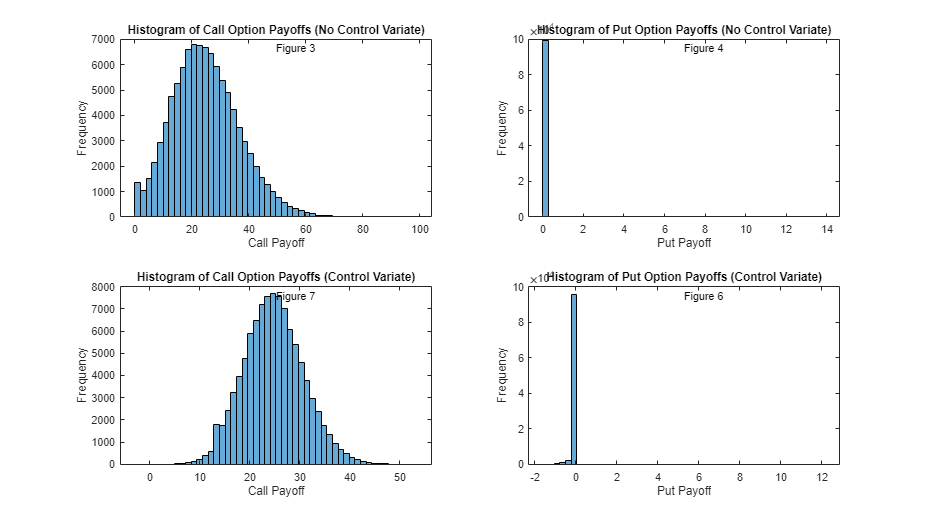

% Initializing the plot
figure('units','normalized','outerposition',[0 0 1 1]);

%Call Payoff histogram without Contol Variate
subplot(2, 2, 1);
histogram(callPayoff, 50);
title('Histogram of Call Option Payoffs (No Control Variate)');
xlabel('Call Payoff');
ylabel('Frequency');
text(0.5,0.95,'Figure 3','Units','normalized');

%Put Payoff histogram without Control Variate
subplot(2, 2, 2);
histogram(putPayoff, 50);
title('Histogram of Put Option Payoffs (No Control Variate)');
xlabel('Put Payoff');
ylabel('Frequency');
text(0.5,0.95,'Figure 4','Units','normalized');

%Call Payoff histogram with Control Variate
subplot(2, 2, 3);
histogram(callPayoffCV, 50);
title('Histogram of Call Option Payoffs (Control Variate)');
xlabel('Call Payoff');
ylabel('Frequency');
text(0.5,0.95,'Figure 7','Units','normalized');

%Put Payoff histogram with Control Variate
subplot(2, 2, 4);
histogram(putPayoffCV, 50);
title('Histogram of Put Option Payoffs (Control Variate)');
xlabel('Put Payoff');
ylabel('Frequency');
text(0.5,0.95,'Figure 6','Units','normalized');

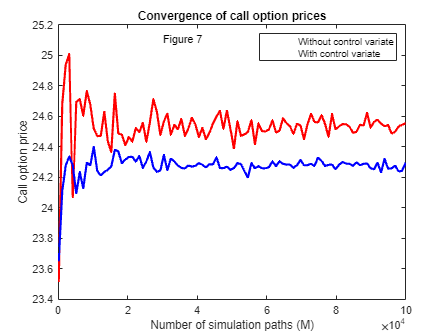

M_simvalue = round(linspace(100, M, 100)); % The number of simulation paths 
callPrices_noCV = zeros(size(M_simvalue)); % storing the call prices without control variate
putPrices_noCV = zeros(size(M_simvalue)); % storing the put prices without control variate
callPrices_CV = zeros(size(M_simvalue)); % storing the call prices with control variate
putPrices_CV = zeros(size(M_simvalue)); % storingg the put prices with control variate

useControlVariate = false; % Start without control variate
for i = 1:length(M_simvalue)
    M_i = M_simvalue(i);
    [callPrice, putPrice, ~, ~, ~, ~] = AsianOptionPricing(S0, K, r, T, sigma, N, M_i, type, useControlVariate);
    callPrices_noCV(i) = callPrice;
    putPrices_noCV(i) = putPrice;
end

useControlVariate = true; % Now with control variate
for i = 1:length(M_simvalue)
    M_i = M_simvalue(i);
    [callPrice, putPrice, ~, ~, ~, ~] = AsianOptionPricing(S0, K, r, T, sigma, N, M_i, type, useControlVariate);
    callPrices_CV(i) = callPrice;
    putPrices_CV(i) = putPrice;
end

% Plot the convergence of call option prices both with and without the
% control variate
figure;
plot(M_simvalue, callPrices_noCV, 'r', 'LineWidth', 2); hold on;
plot(M_simvalue, callPrices_CV, 'b', 'LineWidth', 2);
xlabel('Number of simulation paths (M)');
ylabel('Call option price');
legend('Without control variate', 'With control variate');
title('Convergence of call option prices');
text(0.3,0.95,'Figure 7','Units','normalized');

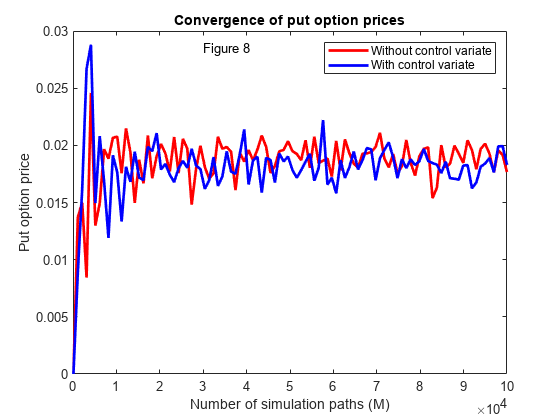

% Plot the convergence of put option prices both with and without the
% control variate
figure;
plot(M_simvalue, putPrices_noCV, 'r', 'LineWidth', 2); hold on;
plot(M_simvalue, putPrices_CV, 'b', 'LineWidth', 2);
xlabel('Number of simulation paths (M)');
ylabel('Put option price');
legend('Without control variate', 'With control variate');
title('Convergence of put option prices');
text(0.3,0.95,'Figure 8','Units','normalized');

Here I am importing a python module into matlab known as 'yfinance'. This is to enable my function to act upon real world adjustable data. The real world data Im currently using is the most recent stock price as the inital stock price and the standard deviaton of the log returns of the stock over the specified period (eg: start date to end date)

% This is the code for importing the python module we will be using and
% setting up te preliminary data
% Import required Python modules
yfinance = py.importlib.import_module('yfinance');

% Define the stock symbol and date range, here you can adjust what stock
% you want to analyze and also the dates you want to focus on.
symbol = 'MSFT'; %Using microsoft as the stock but this can be changed
start_date = '2020-03-06'; % setting start date
end_date = char(py.importlib.import_module('datetime').date.today()); % setting end date

% Fetch historical data
data = yfinance.download(symbol, pyargs('start', start_date, 'end', end_date, 'interval', '1d'));


[*********************100%***********************]  1 of 1 completed


disp(class(data)); %Checking data type to understand how to reformat data and convert to acceptable matlab table

py.pandas.core.frame.DataFrame


% Convert pandas DataFrame to a matlab cell array
data_cell_py = cell(data.values.tolist());
% retrieve column names
column_names_py = cell(data.columns.tolist());
% Convert Python list of lists to matlab cell array of cell arrays
data_cell = cell(numel(data_cell_py), numel(column_names_py));
for i = 1:numel(data_cell_py)
    data_cell(i, :) = cell(data_cell_py{i});
end

% Convert Python strings to matlab character vectors
column_names = cell(size(column_names_py));
for i = 1:numel(column_names_py)
    column_names{i} = char(column_names_py{i});
end

% Convert cell array to matlab table
data_mat = cell2table(data_cell, 'VariableNames', column_names);

% Extract the Close column
close_prices = data_mat.Close;

% Calculating the log returns and subsequently the historic volatility as
% the standard deviation of the log returns
l_returns = diff(log(close_prices));
historicvol = std(l_returns);

rng;% reset the random number generator
S0 = close_prices(end);
ONTM = S0; % On The Money, here the strike price = initial price
OUTM = S0 * 1.02; % Out Of The Money - 2% higher than S0, strike price is higher than intital price and thus a put option would have intrisic value
ITM = S0 * 0.98; % In The Money - 2% lower than S0, strike price is lower than inital price and thus a call option would have intrisic value
K = ONTM; % Strike price, can be set to equal ONTM,OUTM OR ITM depending on preference 2% offset chosen for testing purposes
r = 0.05; % Risk-free interest rate
T = 1; % Time to maturity
sigma = historicvol; % Here the historic volatility of the stock from start date to now is used to predict the current volatilityof the stock
N = 100; % Number of time steps
M = 100000; % Number of simulated paths
type = 'arithmetic'; % Type of Asian option ('arithmetic' or 'geometric')
useControlVariate = false;

% Call the AsianOptionPricing function without controlvariate
[callPrice, putPrice, callPayoff, putPayoff, S] = AsianOptionPricing(S0, K, r, T, sigma, N, M, type,useControlVariate);
 
% Display the results
fprintf('Asian put option price: %f\n', putPrice);

Asian put option price: 0.029418


fprintf('Asian call option price: %f\n', callPrice);

Asian call option price: 7.607611


useControlVariate = true;

% Call the AsianOptionPricing function with control variate
[callPriceCV, putPriceCV, callPayoffCV, putPayoffCV, S] = AsianOptionPricing(S0, K, r, T, sigma, N, M, type,useControlVariate);
 
% Display the results
fprintf('Asian put option price: %f\n', putPriceCV);

Asian put option price: 0.029495


fprintf('Asian call option price: %f\n', callPriceCV);

Asian call option price: 7.248365


Histograms for the new Monte Carlo simulations using the real world data to price Asian opions with and without Control variates

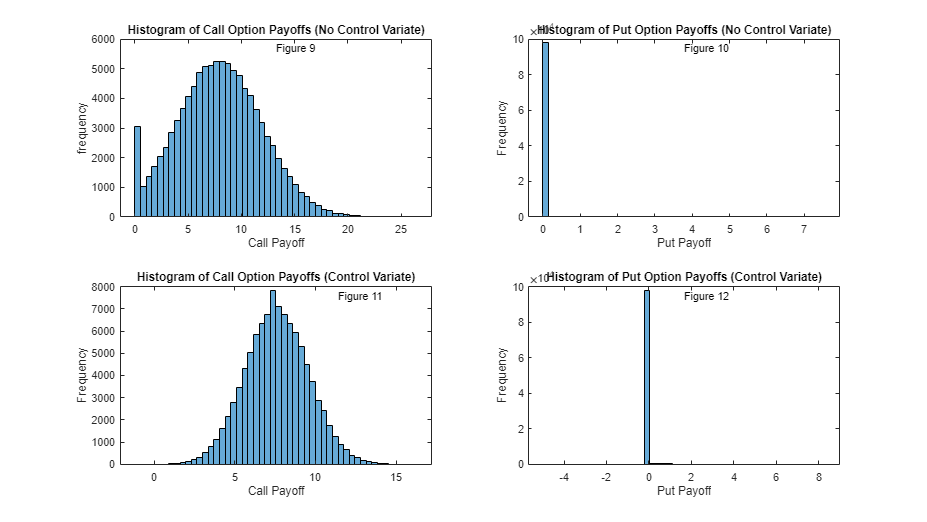

% Initializing the plot
figure('units','normalized','outerposition',[0 0 1 1]);

%Call Payoff histogram without Contol Variate
subplot(2, 2, 1);
histogram(callPayoff, 50);
title('Histogram of Call Option Payoffs (No Control Variate)');
xlabel('Call Payoff');
ylabel('frequency');
text(0.5,0.95,'Figure 9','Units','normalized');

%Put Payoff histogram without Control Variate
subplot(2, 2, 2);
histogram(putPayoff, 50);
title('Histogram of Put Option Payoffs (No Control Variate)');
xlabel('Put Payoff');
ylabel('Frequency');
text(0.5,0.95,'Figure 10','Units','normalized');

%Call Payoff histogram with Control Variate
subplot(2, 2, 3);
histogram(callPayoffCV, 50);
title('Histogram of Call Option Payoffs (Control Variate)');
xlabel('Call Payoff');
ylabel('Frequency');
text(0.7,0.95,'Figure 11','Units','normalized');

%Put Payoff histogram with Control Variate
subplot(2, 2, 4);
histogram(putPayoffCV, 50);
title('Histogram of Put Option Payoffs (Control Variate)');
xlabel('Put Payoff');
ylabel('Frequency');
text(0.5,0.95,'Figure 12','Units','normalized');

Graphs plottng the convergence for Asian call and put options both with and without control variates using the imported data and with Monte Carlo simulation

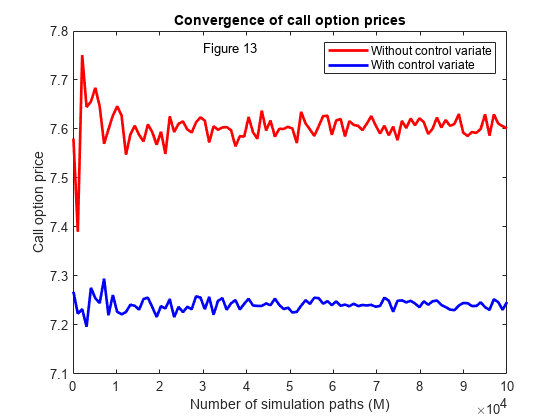

M_simvalue = round(linspace(100, M, 100)); % The number of simulation paths 
callPrices_noCV = zeros(size(M_simvalue)); % storing the call prices without control variate
putPrices_noCV = zeros(size(M_simvalue)); % storing the put prices without control variate
callPrices_CV = zeros(size(M_simvalue)); % storing the call prices with control variate
putPrices_CV = zeros(size(M_simvalue)); % storingg the put prices with control variate

useControlVariate = false; % Start without control variate
for i = 1:length(M_simvalue)
    M_i = M_simvalue(i);
    [callPrice, putPrice, ~, ~, ~, ~] = AsianOptionPricing(S0, K, r, T, sigma, N, M_i, type, useControlVariate);
    callPrices_noCV(i) = callPrice;
    putPrices_noCV(i) = putPrice;
end

useControlVariate = true; % Now with control variate
for i = 1:length(M_simvalue)
    M_i = M_simvalue(i);
    [callPrice, putPrice, ~, ~, ~, ~] = AsianOptionPricing(S0, K, r, T, sigma, N, M_i, type, useControlVariate);
    callPrices_CV(i) = callPrice;
    putPrices_CV(i) = putPrice;
end

% Plot the convergence of call option prices both with and without the
% control variate
figure;
plot(M_simvalue, callPrices_noCV, 'r', 'LineWidth', 2); hold on;
plot(M_simvalue, callPrices_CV, 'b', 'LineWidth', 2);
xlabel('Number of simulation paths (M)');
ylabel('Call option price');
legend('Without control variate', 'With control variate');
title('Convergence of call option prices');
text(0.3,0.95,'Figure 13','Units','normalized');

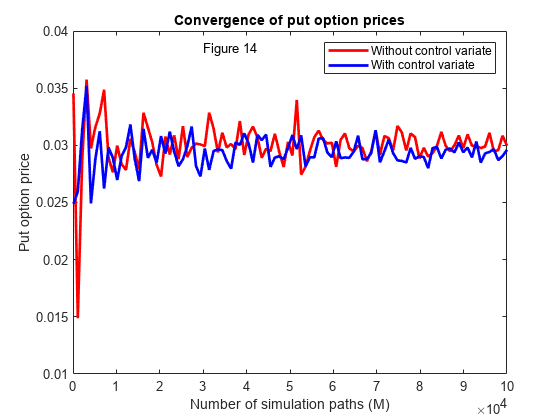

% Plot the convergence of put option prices both with and without the
% control variate
figure;
plot(M_simvalue, putPrices_noCV, 'r', 'LineWidth', 2); hold on;
plot(M_simvalue, putPrices_CV, 'b', 'LineWidth', 2);
xlabel('Number of simulation paths (M)');
ylabel('Put option price');
legend('Without control variate', 'With control variate');
title('Convergence of put option prices');
text(0.3,0.95,'Figure 14','Units','normalized');